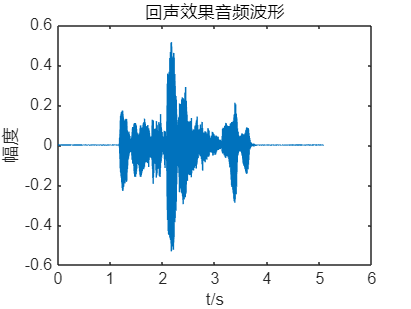

clc;clear;
[y,Fs]=audioread('dspx1.wav');
n = length(y); 
delay=10000;
a=zeros (n+delay,1);
a(delay+1:n+delay)=0.5.*y ;
y (n+delay, : )=0;
y=y+a;
t = (0:length(y)-1) / Fs;
sound (y, Fs);
figure;
plot(t, y) ;
title('回声效果音频波形')
xlabel('t/s') ;
ylabel('幅度');